RMSE = zeros(10,1);
[T1,Y1] = analytic([0;0.6],0.01,2)

T1 =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Y1 =          0    0.6000
    0.0054    0.0054
    0.0098    0.0098
    0.0134    0.0134
    0.0162    0.0162
    0.0185    0.0185
    0.0202    0.0202
    0.0215    0.0215
    0.0224    0.0224
    0.0230    0.0230


plot(T1,Y1(:,1),"r")
hold on

[T,Y] = eulersolver([0;0.6],0.01,2,@derivs)

T =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Y =          0    0.6000
    0.0060    0.4800
    0.0108    0.3802
    0.0146    0.2972
    0.0176    0.2284
    0.0199    0.1715
    0.0216    0.1245
    0.0228    0.0858
    0.0237    0.0540
    0.0242    0.0281


plot(T,Y(:,1),"g")
hold on

RMSE(1) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:



[T,Y] = rungekutta([0;0.6],0.01,2,@derivs)

Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t =

T =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Y =          0    0.6000
    0.0054    0.4896
    0.0098    0.3963
    0.0134    0.3176
    0.0162    0.2514
    0.0185    0.1957
    0.0202    0.1490
    0.0215    0.1099
    0.0224    0.0772
    0.0230    0.0500


plot(T,Y(:,1),"b")
hold on

RMSE(2) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 2.741713e-08:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:



[T,Y] = adams3rd([0;0.6],0.01,2,@derivs)

Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t =

t =          0
    0.0100
         0
         0
         0
         0
         0
         0
         0
         0


t =          0
    0.0100
    0.0200
         0
         0
         0
         0
         0
         0
         0


Y_2 N 9.848365e-03 
Y_2 N 3.962960e-01 
Step 3: t = 0.0300, w =  0.013416609461728
Step 3.174860e-01: t = Step 4: t = 0.0400, w =  0.016257632446366
Step 2.511631e-01: t = Step 5: t = 0.0500, w =  0.018489679368689
Step 1.954021e-01: t = Step 6: t = 0.0600, w =  0.020208902837457
Step 1.486324e-01: t = Step 7: t = 0.0700, w =  0.021498841743002
Step 1.094865e-01: t = Step 8: t = 0.0800, w =  0.022429743457239
Step 7.681091e-02: t = Step 9: t = 0.0900, w =  0.023061434021789
Step 4.961991e-02: t = Step 10: t = 0.1000, w =  0.023444530722388
Step 2.707631e-02: t = Step 11: t = 0.1100, w =  0.023621939938547
Step 8.467328e-03: t = Step 12: t = 0.1200, w =  0.023629962549431
Step -6.813087e-03: t = Step 13: t = 0.1300, w =  0.023499298641365
Step -1.928038e-02: t = Step 14: t = 0.1400, w =  0.023255879672152
Step -2.937276e-02: t = Step 15: t = 0.1500, w =  0.022921585701857
Step -3.746268e-02: t = Step 16: t = 0.1600, w =  0.022514852855237
Step -4.386663e-02: t = Step 17: t = 0.1700, w =

T =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Y =          0    0.6000
    0.0054    0.4896
    0.0098    0.3963
    0.0134    0.3175
    0.0163    0.2512
    0.0185    0.1954
    0.0202    0.1486
    0.0215    0.1095
    0.0224    0.0768
    0.0231    0.0496


plot(T,Y(:,1),"m")
hold on

RMSE(3) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 2.741713e-08:
RMSE: 5.751350e-06:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:



[T,Y] = adams4th([0;0.6],0.01,2,@derivs)

Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t =

t =          0
    0.0100
         0
         0
         0
         0
         0
         0
         0
         0


t =          0
    0.0100
    0.0200
         0
         0
         0
         0
         0
         0
         0


t =          0
    0.0100
    0.0200
    0.0300
         0
         0
         0
         0
         0
         0


Step 4: t = 0.0000, w =  0.016241226027525
Step 2.514267e-01: t = Step 5: t = 0.0000, w =  0.018468096246598
Step 1.957489e-01: t = Step 6: t = 0.0000, w =  0.020183984490593
Step 1.490330e-01: t = Step 7: t = 0.0000, w =  0.021472164259324
Step 1.099157e-01: t = Step 8: t = 0.0000, w =  0.022402283271828
Step 7.725297e-02: t = Step 9: t = 0.0000, w =  0.023034103770124
Step 5.006023e-02: t = Step 10: t = 0.0000, w =  0.023417841480501
Step 2.750667e-02: t = Step 11: t = 0.0000, w =  0.023596354857593
Step 8.880292e-03: t = Step 12: t = 0.0000, w =  0.023605719141998
Step -6.421344e-03: t = Step 13: t = 0.0000, w =  0.023476591460464
Step -1.891300e-02: t = Step 14: t = 0.0000, w =  0.023234781103295
Step -2.903092e-02: t = Step 15: t = 0.0000, w =  0.022902137016357
Step -3.714706e-02: t = Step 16: t = 0.0000, w =  0.022497031540614
Step -4.357689e-02: t = Step 17: t = 0.0000, w =  0.022034956747570
Step -4.858895e-02: t = Step 18: t = 0.0000, w =  0.021528907353760
Step -5.241100e-02

T =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Y =          0    0.6000
    0.0054    0.4896
    0.0098    0.3963
    0.0134    0.3176
    0.0162    0.2514
    0.0185    0.1957
    0.0202    0.1490
    0.0215    0.1099
    0.0224    0.0773
    0.0230    0.0501


plot(T,Y(:,1),"k")
hold on

RMSE(4) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 2.741713e-08:
RMSE: 5.751350e-06:
RMSE: 7.992358e-07:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:



[T,Y] = adams5th([0;0.6],0.01,2,@derivs)

Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t =

t =          0
    0.0100
         0
         0
         0
         0
         0
         0
         0
         0


t =          0
    0.0100
    0.0200
         0
         0
         0
         0
         0
         0
         0


t =          0
    0.0100
    0.0200
    0.0300
         0
         0
         0
         0
         0
         0


Step 5: t = 0.0000, w =  0.018470277091355
Step 1.957140e-01: t = Step 6: t = 0.0000, w =  0.020187017002038
Step 1.489844e-01: t = Step 7: t = 0.0000, w =  0.021475604178395
Step 1.098606e-01: t = Step 8: t = 0.0000, w =  0.022405994145070
Step 7.719351e-02: t = Step 9: t = 0.0000, w =  0.023037910487430
Step 4.999922e-02: t = Step 10: t = 0.0000, w =  0.023421619164857
Step 2.744612e-02: t = Step 11: t = 0.0000, w =  0.023600066000213
Step 8.820793e-03: t = Step 12: t = 0.0000, w =  0.023609249856184
Step -6.477967e-03: t = Step 13: t = 0.0000, w =  0.023479973587213
Step -1.896725e-02: t = Step 14: t = 0.0000, w =  0.023237914937897
Step -2.908121e-02: t = Step 15: t = 0.0000, w =  0.022905091502406
Step -3.719449e-02: t = Step 16: t = 0.0000, w =  0.022499718693539
Step -4.362005e-02: t = Step 17: t = 0.0000, w =  0.022037464113119
Step -4.862924e-02: t = Step 18: t = 0.0000, w =  0.021531154905771
Step -5.244713e-02: t = Step 19: t = 0.0000, w =  0.020991875024874
Step -5.527015e-

T =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


Y =          0    0.6000
    0.0054    0.4896
    0.0098    0.3963
    0.0134    0.3176
    0.0162    0.2514
    0.0185    0.1957
    0.0202    0.1490
    0.0215    0.1099
    0.0224    0.0772
    0.0230    0.0500


plot(T,Y(:,1),"c")
hold on

RMSE(5) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 2.741713e-08:
RMSE: 5.751350e-06:
RMSE: 7.992358e-07:
RMSE: 1.126996e-07:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:
RMSE: 0:




[T,Y] = rk45([0;0.6],0.01,2,0.000001,@derivs)

Step 0: t = 0.0000, w =  0.000000000000000
Step 6.000000e-01: t = Step 1: t = 0.0000, w =  0.000020880927921
Step 5.995824e-01: t = Step 2: t = 0.0001, w =  0.000038716966420
Step 5.992256e-01: t = Step 3: t = 0.0001, w =  0.000054565416883
Step 5.989085e-01: t = Step 4: t = 0.0001, w =  0.000069070440686
Step 5.986183e-01: t = Step 5: t = 0.0001, w =  0.000082643453308
Step 5.983468e-01: t = Step 6: t = 0.0002, w =  0.000095557047112
Step 5.980884e-01: t = Step 7: t = 0.0002, w =  0.000107997227803
Step 5.978394e-01: t = Step 8: t = 0.0002, w =  0.000120093692302
Step 5.975974e-01: t = Step 9: t = 0.0002, w =  0.000131938512063
Step 5.973603e-01: t = Step 10: t = 0.0002, w =  0.000143597904398
Step 5.971269e-01: t = Step 11: t = 0.0003, w =  0.000155120008382
Step 5.968963e-01: t = Step 12: t = 0.0003, w =  0.000166540001501
Step 5.966677e-01: t = Step 13: t = 0.0003, w =  0.000177883835298
Step 5.964406e-01: t = Step 14: t = 0.0003, w =  0.000189170687259
Step 5.962147e-01: t = Step 

T =     0.0348    0.0646    0.0910    0.1152    0.1379    0.1595    0.1803    0.2006    0.2204    0.2399    0.2592    0.2783    0.2974    0.3163    0.3351    0.3540    0.3727    0.3915    0.4102    0.4290    0.4477    0.4664    0.4851    0.5039    0.5226    0.5413    0.5600    0.5788    0.5975    0.6162    0.6350    0.6537    0.6725    0.6913    0.7100    0.7288    0.7476    0.7664    0.7852    0.8040    0.8228    0.8416    0.8604    0.8792    0.8980    0.9169    0.9357    0.9545    0.9734    0.9922


Y =     0.0000    0.5996
    0.0000    0.5992
    0.0001    0.5989
    0.0001    0.5986
    0.0001    0.5983
    0.0001    0.5981
    0.0001    0.5978
    0.0001    0.5976
    0.0001    0.5974
    0.0001    0.5971


plot(T,Y(:,1),"c--")
hold on


[T1,Y1] = analytic([0;0.6],0.05,2)

T1 =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


Y1 =          0    0.6000
    0.0185    0.0185
    0.0234    0.0234
    0.0229    0.0229
    0.0204    0.0204
    0.0175    0.0175
    0.0146    0.0146
    0.0121    0.0121
    0.0100    0.0100
    0.0082    0.0082


[T,Y] = eulersolver([0;0.6],0.05,2,@derivs)

T =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


Y =          0    0.6000
    0.0300   -0.0000
    0.0300   -0.0960
    0.0252   -0.0960
    0.0204   -0.0806
    0.0164   -0.0653
    0.0131   -0.0524
    0.0105   -0.0419
    0.0084   -0.0336
    0.0067   -0.0268


plot(T,Y(:,1),"g--")
hold on

RMSE(7) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 2.741713e-08:
RMSE: 5.751350e-06:
RMSE: 7.992358e-07:
RMSE: 1.126996e-07:
RMSE: 0:
RMSE: 2.214587e-03:
RMSE: 0:
RMSE: 0:
RMSE: 0:



[T,Y] = rungekutta([0;0.6],0.05,2,@derivs)

Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.600000000000000
Step 1: t = 0.0500, w =  0.018350000000000
Step 1.976400e-01: t = Step 2: t = 0.1000, w =  0.0233

T =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


Y =          0    0.6000
    0.0183    0.1976
    0.0233    0.0292
    0.0228   -0.0360
    0.0204   -0.0566
    0.0175   -0.0585
    0.0146   -0.0534
    0.0121   -0.0462
    0.0100   -0.0390
    0.0082   -0.0324


plot(T,Y(:,1),"b--")
hold on

RMSE(8) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 2.741713e-08:
RMSE: 5.751350e-06:
RMSE: 7.992358e-07:
RMSE: 1.126996e-07:
RMSE: 0:
RMSE: 2.214587e-03:
RMSE: 2.886940e-05:
RMSE: 0:
RMSE: 0:



[T1,Y1] = analytic([0;0.6],0.1,2)

T1 =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


Y1 =          0    0.6000
    0.0234    0.0234
    0.0204    0.0204
    0.0146    0.0146
    0.0100    0.0100
    0.0067    0.0067
    0.0045    0.0045
    0.0030    0.0030
    0.0020    0.0020
    0.0014    0.0014


[T,Y] = eulersolver([0;0.6],0.1,2,@derivs)

T =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


Y =          0    0.6000
    0.0600   -0.6000
   -0.0000    0.2160
    0.0216   -0.2160
   -0.0000    0.0778
    0.0078   -0.0778
   -0.0000    0.0280
    0.0028   -0.0280
   -0.0000    0.0101
    0.0010   -0.0101


plot(T,Y(:,1),"k--")
hold on

RMSE(9) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 2.741713e-08:
RMSE: 5.751350e-06:
RMSE: 7.992358e-07:
RMSE: 1.126996e-07:
RMSE: 0:
RMSE: 2.214587e-03:
RMSE: 2.886940e-05:
RMSE: 9.589101e-03:
RMSE: 0:



[T,Y] = rungekutta([0;0.6],0.1,2,@derivs)

Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.000000000000000
Step 0: t = 0.0000, w =  0.600000000000000
Step 1: t = 0.1000, w =  0.020000000000000
Step 8.224000e-02: t = Step 2: t = 0.2000, w =  0.018816000000000
Step -3.139430e-02: t = Step 3: t = 0.3000, w =  0.014076569600000
Step -4.444391e-02: t = Step 4: t = 0.4000, w =  0.009832344453120
Step -3.612179e-02: t = Step 5: t = 0.5000, w =  0.006698523178435
Step -2.592676e-02: t = Step 6: t = 0.6000, w =  0.004519600960012
Step -1.784388e-02: t = Step 7: t = 0.7000, w =  0.003037758023722
Step -1.208762e-02: t = Step 8: t = 0.8000, w =  0.002038626841954
Step -8.137360e-

T =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


Y =          0    0.6000
    0.0200    0.0822
    0.0188   -0.0314
    0.0141   -0.0444
    0.0098   -0.0361
    0.0067   -0.0259
    0.0045   -0.0178
    0.0030   -0.0121
    0.0020   -0.0081
    0.0014   -0.0055


plot(T,Y(:,1),"m--")
hold on

RMSE(10) = sqrt(mean((Y1(:,1) - Y(:,1)).^2));
fprintf('RMSE: %d:\n', RMSE);

RMSE: 3.215883e-04:
RMSE: 2.741713e-08:
RMSE: 5.751350e-06:
RMSE: 7.992358e-07:
RMSE: 1.126996e-07:
RMSE: 0:
RMSE: 2.214587e-03:
RMSE: 2.886940e-05:
RMSE: 9.589101e-03:
RMSE: 8.356885e-04:


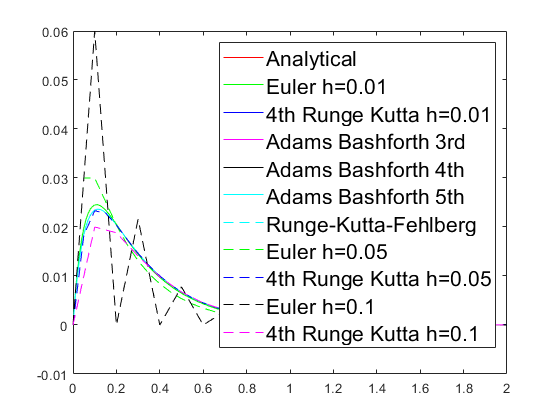



xlim([0,2])
legend({"Analytical","Euler h=0.01","4th Runge Kutta h=0.01","Adams Bashforth 3rd","Adams Bashforth 4th","Adams Bashforth 5th","Runge-Kutta-Fehlberg","Euler h=0.05","4th Runge Kutta h=0.05","Euler h=0.1","4th Runge Kutta h=0.1"},'FontSize',16)